# Extract all the tst, tsw and kx values required fro the given dx

% dx matrix from the run function
clear; 
Path = "OscParamSolver\resultsOscParamSolver\";
dirInfo = dir(Path);
fileNames = {dirInfo(~[dirInfo.isdir]).name};
% fileNames = fileNames(2:end);

% temp = linspace(1,2,21);
% dx = [linspace(0,1,20),temp(2:end)];
% dx = dx(1:30);

dx = [];
tst = [];
tsw = [];
kx = [];
yi = [];

for k = 1:length(fileNames)
    % filename = "run_"+ floor(dx(k)) + "p" + floor(mod(dx(k),1)*100) + "ms.mat";
    sol = load("OscParamSolver\resultsOscParamSolver\" + fileNames(k));
    sol = sol.out;

    P_max = 1e1;

    penalties = sum(sol.P_fende)<P_max && sum(sol.P_fendr)<P_max;
    penalties = penalties && sum(sol.P_fric)<P_max && sum(sol.P_grfx_neg)<P_max && sum(sol.P_grfx_pos)<P_max && sum(sol.P_grfy)<P_max;
    penalties = penalties && sum(sol.P_ypos)<P_max && sum(sol.P_yneg)<P_max && sum(sol.P_xpos)<P_max && sum(sol.P_xneg)<P_max;

    if (penalties && sol.q(5)>0.15)
        dx = [dx,mean(sol.q(5,:))];
        tst = [tst,sol.tst(1)];
        tsw = [tsw,sol.tsw(1)];
        kx = [kx,sol.kx(1)];
        yi = [yi,sol.q(2,1)];
    end
end

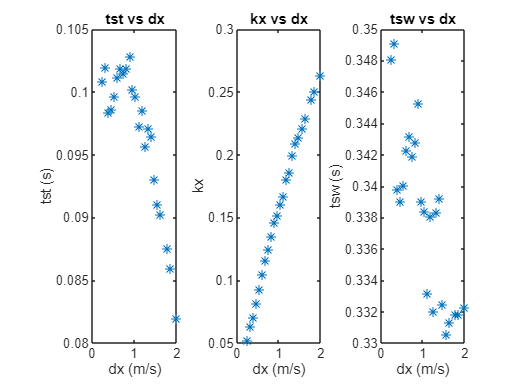

subplot(1,3,1);
plot(dx,tst,'*');
title("tst vs dx");
xlabel("dx (m/s)");
ylabel("tst (s)");

subplot(1,3,2);
plot(dx,kx,'*');
title("kx vs dx");
xlabel("dx (m/s)");
ylabel("kx");

subplot(1,3,3);
plot(dx,tsw,'*');
title("tsw vs dx");
xlabel("dx (m/s)");
ylabel("tsw (s)");

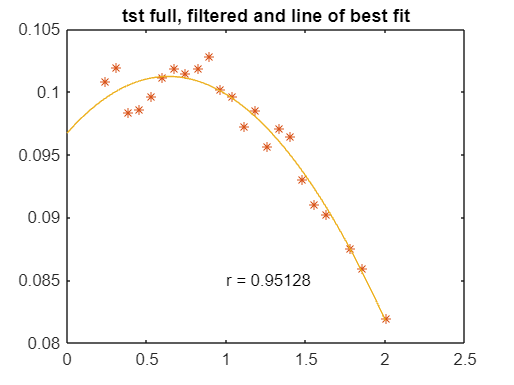

[dx_sort,I] = sort(dx);
tst_sort = tst(I);
[tst_noOut,TFrm_tst] = rmoutliers(tst_sort,"movmedian",0.3,"SamplePoints",dx_sort);

kx_sort = kx(I);
[kx_noOut,TFrm_kx] = rmoutliers(kx_sort,"movmedian",0.3,"SamplePoints",dx_sort);

tsw_sort = tsw(I);
[tsw_noOut,TFrm_tsw] = rmoutliers(tsw_sort,"movmedian",0.3,"SamplePoints",dx_sort);

[kx_sol,info_kx] = polyfit(dx,kx,1);
[tst_sol,info_tst] = polyfit(dx_sort(~TFrm_tst),tst_noOut,3);
[tsw_sol,info_tsw] = polyfit(dx_sort(~TFrm_tsw),tsw_noOut,5);

t = linspace(0,2,100);

figure
plot(dx,tst,'*')
hold on
plot(dx_sort(~TFrm_tst),tst_noOut,'*')
title("tst full, filtered and line of best fit")
plot(t,polyval(tst_sol,t))
str = "r = "+info_tst.rsquared;
text(1,0.085,str)
hold off

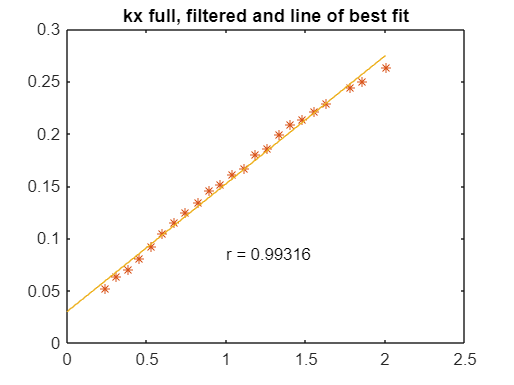


figure
plot(dx,kx,'*')
hold on
plot(dx_sort(~TFrm_kx),kx_noOut,'*')
title("kx full, filtered and line of best fit")
plot(t,polyval(kx_sol,t))
str = "r = "+info_kx.rsquared;
text(1,0.085,str)
hold off

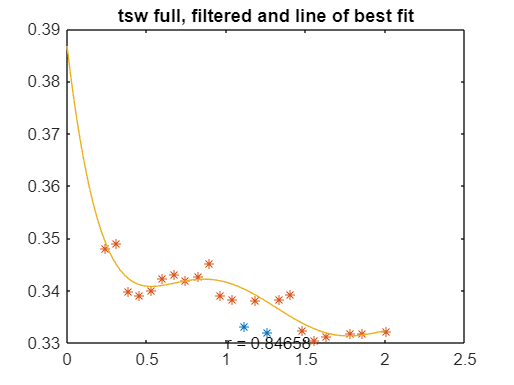


figure
plot(dx,tsw,'*')
hold on
plot(dx_sort(~TFrm_tsw),tsw_noOut,'*')
title("tsw full, filtered and line of best fit")
plot(t,polyval(tsw_sol,t))
str = "r = "+info_tsw.rsquared;
text(1,0.33,str)
hold off

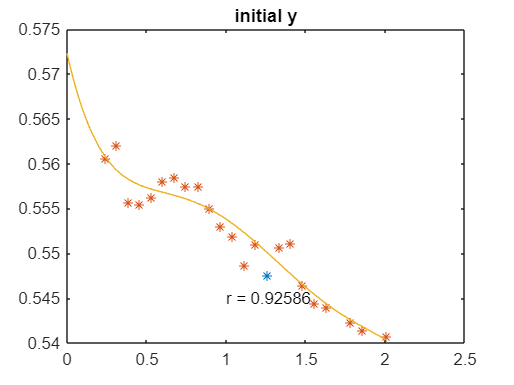

y_sort = yi(I);
[y_noOut,TFrm_y] = rmoutliers(y_sort,"movmedian",0.3,"SamplePoints",dx_sort);

[y_sol,info_y] = polyfit(dx_sort(~TFrm_y),y_noOut,5);

figure;
plot(dx,yi,'*')
hold on
plot(dx_sort(~TFrm_y),y_noOut,'*')
title("initial y");
plot(t,polyval(y_sol,t))
str = "r = "+info_y.rsquared;
text(1,0.545,str)
hold off


save('OscParamSolver/fits/fit2.mat','tst_sol','kx_sol','tsw_sol','y_sol')

[kx_sol,info_kx] = polyfit(dx,kx,1);
[tst_sol,info_tst] = polyfit(dx,tst,3);
[tsw_sol,info_tsw] = polyfit(dx,tsw,5);

t = linspace(0,2,100);

margin_w = 60;
margin_h = 50;
w_one = 200;
h_one = 200;
w = w_one*3 + 3.5*margin_w; h = h_one + 1.5*margin_h;

f = figure

f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


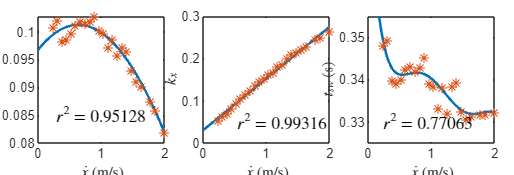

size_big = gcf; size_big.Position(3) = w; size_big.Position(4) = h;
subplot(1,3,1);
size = gca; size.Position(1) = margin_w/w; size.Position(2) = margin_h/h;
size.Position(3) = w_one/w; size.Position(4) = h_one/h;
plot(t,polyval(tst_sol,t),"LineWidth",1.5)
hold on
plot(dx,tst,'*');
xlabel("$\dot x$ (m/s)","Interpreter","latex");
ylabel("$t_{st}$ (s)","Interpreter","latex");
str = "$r^2 = "+info_tst.rsquared + "$";
text(0.25,0.085,str,"Interpreter","latex")
hold off

subplot(1,3,2);
size = gca; size.Position(1) = (w_one + 2*margin_w)/w; size.Position(2) = margin_h/h;
size.Position(3) = w_one/w; size.Position(4) = h_one/h;
plot(t,polyval(kx_sol,t),"LineWidth",1.5)
hold on
plot(dx,kx,'*');
xlabel("$\dot x$ (m/s)","Interpreter","latex");
ylabel("$k_x$","Interpreter","latex");
str = "$r^2 = "+info_kx.rsquared + "$";
text(0.5,0.05,str,"Interpreter","latex")
hold off

subplot(1,3,3);
size = gca; size.Position(1) = (2*w_one + 3*margin_w)/w; size.Position(2) = margin_h/h;
size.Position(3) = w_one/w; size.Position(4) = h_one/h;
plot(t,polyval(tsw_sol,t),"LineWidth",1.5)
hold on
plot(dx,tsw,'*');
xlabel("$\dot x$ (m/s)","Interpreter","latex");
ylabel("$t_{sw}$ (s)","Interpreter","latex");
str = "$r^2 = "+info_tsw.rsquared + "$";
text(0.2,0.33,str,"Interpreter","latex")
ylim([0.325 0.355])
hold off

saveas(f,"param_interpolate_trajOpt","jpg")